clear; close all;


[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

FPs = obj.MixedFP;


session_control = find(obj.Label=="Control");
session_chemo = find(obj.Label=="Chemo");

hd_control = cell(3, 2);
hd_chemo = cell(3, 2);
rt_control = cell(3, 2);
rt_chemo = cell(3, 2);

for fp = 1:3
    for p = 1:2
        hd_control{fp, p} = obj.HDSortedControl{fp, p};
        hd_chemo{fp, p} = obj.HDSortedChemo{fp, p};

        rt_control{fp, p} = hd_control{fp, p} - FPs(fp);
        rt_chemo{fp, p} = hd_chemo{fp, p} - FPs(fp);

        rt_control{fp, p} = rt_control{fp, p}(rt_control{fp, p}>=0);
        rt_chemo{fp, p} = rt_chemo{fp, p}(rt_chemo{fp, p}>=0);
    end
end


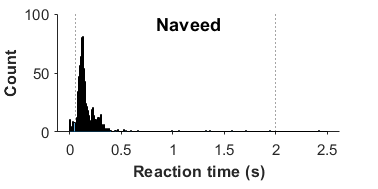

rt_lower = .05;
rt_upper = 2;

fig_rt_hist = figure(30); clf(fig_rt_hist);
set(fig_rt_hist, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 4], 'Color', 'w', 'toolbar', 'none');

ax_rt_hist = axes(fig_rt_hist, 'NextPlot', 'add', 'Units', 'centimeters', 'Position', [1.2 1.2 6 2.5], 'FontSize', 9, 'TickDir', 'out');

histogram(ax_rt_hist, [cell2mat(rt_control(:)); cell2mat(rt_chemo(:))], 'BinEdges', 0:0.01:2.5, 'LineWidth', .1);
xline(ax_rt_hist, [rt_lower rt_upper], 'LineWidth', .5, 'LineStyle', ':', 'Color', 'k');

ax_rt_hist.XLabel.String = "Reaction time (s)";
ax_rt_hist.XLabel.FontWeight = "bold";
ax_rt_hist.YLabel.String = "Count";
ax_rt_hist.YLabel.FontWeight = "bold";

set_fig_title(fig_rt_hist, obj.Subject, 'FontSize', 11);

fig_name = sprintf("Test_%s_RT_trim_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_rt_hist, fig_path, 'Resolution', 600);

trim_rt = @(x) x(x>=rt_lower & x<=rt_upper);
rt_control = cellfun(@(x) trim_rt(x), rt_control, 'UniformOutput', false);
rt_chemo = cellfun(@(x) trim_rt(x), rt_chemo, 'UniformOutput', false);


hd_bins = 0:0.001:3;
band_width = 0.05;
n_boot = 1000;

kde_hd_pdf = @(x) ksdensity(x, hd_bins, 'Function', 'pdf', 'Bandwidth', band_width);
kde_hd_cdf = @(x) ksdensity(x, hd_bins, 'Function', 'cdf', 'Bandwidth', band_width);

hd_pd_control = cellfun(@(x) kde_hd_pdf(x), hd_control, 'UniformOutput', false);
hd_pd_chemo = cellfun(@(x) kde_hd_pdf(x), hd_chemo, 'UniformOutput', false);

hd_pd_max = max(max(cellfun(@(x, y) max([x y]), hd_pd_control, hd_pd_chemo)));
hd_pd_ylim = .5 * (ceil(hd_pd_max) + round(hd_pd_max));


rt_bins = 0:0.001:rt_upper;

kde_rt_pdf = @(x) ksdensity(x, rt_bins, 'Function', 'pdf', 'Bandwidth', band_width);
kde_rt_cdf = @(x) ksdensity(x, rt_bins, 'Function', 'cdf', 'Bandwidth', band_width);

rt_pd_control = cellfun(@(x) kde_rt_pdf(x), rt_control, 'UniformOutput', false);
rt_pd_chemo = cellfun(@(x) kde_rt_pdf(x), rt_chemo, 'UniformOutput', false);

rt_pd_max = max(max(cellfun(@(x, y) max([x y]), rt_pd_control, rt_pd_chemo)));
rt_pd_ylim = .5 * (ceil(rt_pd_max) + round(rt_pd_max));


[~, hd_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), hd_control, hd_chemo);
hd_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), hd_control, hd_chemo);

[~, rt_p_KS] = cellfun(@(x1, x2) kstest2(x1, x2), rt_control, rt_chemo);
rt_p_RS = cellfun(@(x1, x2) ranksum(x1, x2), rt_control, rt_chemo);



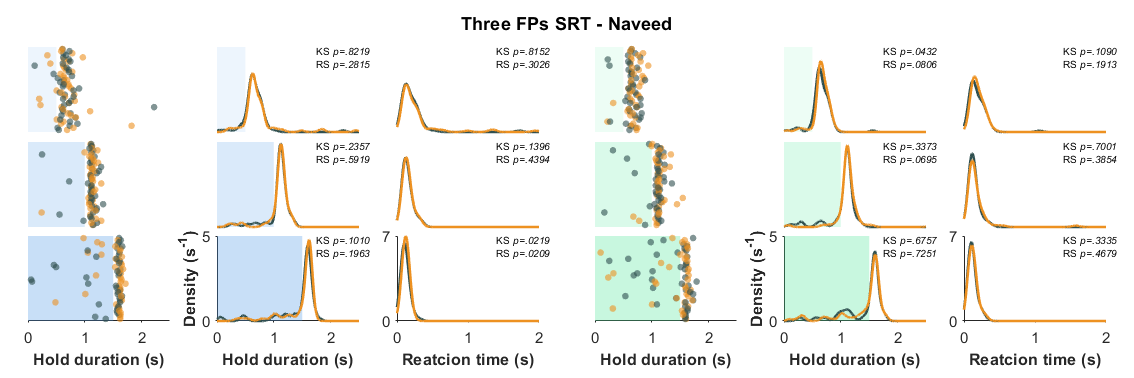

n_show = 40;

fig_srt = figure(31); clf(fig_srt);
set(fig_srt, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 24 8], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_srt, sprintf("Three FPs SRT - %s", obj.Subject), 'FontSize', 11);

ax_hd_s = cell(3,2);
ax_hd_pd = cell(3,2);
ax_rt_pd = cell(3,2);

ax_w = 3; ax_h = 1.8;
ax_w_sep = 1; ax_h_sep = .2;

for fp = 1:3
    for p = 1:2
    
        hd_this = [hd_control{fp, p}(randperm(length(hd_control{fp, p}), n_show)); 
            hd_chemo{fp, p}(randperm(length(hd_chemo{fp, p}), n_show))];
        c_this = [repmat(GPSColor.Control, n_show, 1); 
            repmat(GPSColor.Treat, n_show, 1)];
        id_this = [1:n_show 1:n_show]';
        perm_this = randperm(2*n_show);

        % Hold duration scatter
        ax_hd_s{fp, p} = axes(fig_srt, "Units", "centimeters", "Position", [.6+(p-1)*3*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YColor', 'none');
        fill(ax_hd_s{fp, p}, [0 FPs(fp) FPs(fp) 0], [0 0 n_show+1 n_show+1], 'r', ...
            'EdgeColor', 'none', 'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', 0.3*FPs(fp)/max(FPs))
        scatter(ax_hd_s{fp, p}, hd_this(perm_this), id_this(perm_this), 16, c_this(perm_this, :), 'fill', ...
            'MarkerFaceAlpha', .6, 'MarkerEdgeAlpha', .6);
        set(ax_hd_s{fp, p}, 'XLim', [0 2.5], 'YLim', [0 n_show+1], 'YTickLabel', []);
        switch fp
            case 3
                ax_hd_s{fp, p}.XLabel.String = "Hold duration (s)";
                ax_hd_s{fp, p}.XLabel.FontWeight = "bold";
            otherwise
                set(ax_hd_s{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end

        % Hold duration PDF
        ax_hd_pd{fp, p} = axes(fig_srt, "Units", "centimeters", "Position", [.6+(3*p-2)*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
        fill(ax_hd_pd{fp, p}, [0 FPs(fp) FPs(fp) 0], [0 0 hd_pd_ylim hd_pd_ylim], 'r', ...
            'EdgeColor', 'none', 'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', 0.3*FPs(fp)/max(FPs))
        plot(ax_hd_pd{fp, p}, hd_bins, hd_pd_control{fp, p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
        plot(ax_hd_pd{fp, p}, hd_bins, hd_pd_chemo{fp, p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);
        set(ax_hd_pd{fp, p}, 'XLim', [0 2.5], 'YLim', [0 hd_pd_ylim], 'YTick', [0 hd_pd_ylim]);
        switch fp
            case 3
                ax_hd_pd{fp, p}.XLabel.String = "Hold duration (s)";
                ax_hd_pd{fp, p}.XLabel.FontWeight = "bold";
                ax_hd_pd{fp, p}.YLabel.String = "Density (s^{-1})";
                ax_hd_pd{fp, p}.YLabel.FontWeight = "bold";
            otherwise
                set(ax_hd_pd{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end
        if hd_p_KS(fp, p)<.0001
            text(ax_hd_pd{fp, p}, 1.08*ax_hd_pd{fp, p}.XLim(2), .95*ax_hd_pd{fp, p}.YLim(2), "KS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6);
        else
            p_str = sprintf("KS \\it{p}=%.4f", hd_p_KS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            text(ax_hd_pd{fp, p}, 1.08*ax_hd_pd{fp, p}.XLim(2), .95*ax_hd_pd{fp, p}.YLim(2), p_str, ...
                'HorizontalAlignment', 'right', 'FontSize', 6);
        end
        if hd_p_RS(fp, p)<.0001
            text(ax_hd_pd{fp, p}, 1.08*ax_hd_pd{fp, p}.XLim(2), .8*ax_hd_pd{fp, p}.YLim(2), "RS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6);
        else
            p_str = sprintf("RS \\it{p}=%.4f", hd_p_RS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            text(ax_hd_pd{fp, p}, 1.08*ax_hd_pd{fp, p}.XLim(2), .8*ax_hd_pd{fp, p}.YLim(2), p_str, ...
                'HorizontalAlignment', 'right', 'FontSize', 6);
        end

        % Reaction time PDF
        ax_rt_pd{fp, p} = axes(fig_srt, "Units", "centimeters", "Position", [.4+(3*p-1)*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
        plot(ax_rt_pd{fp, p}, rt_bins, rt_pd_control{fp, p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
        plot(ax_rt_pd{fp, p}, rt_bins, rt_pd_chemo{fp, p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);
        set(ax_rt_pd{fp, p}, 'XLim', [0 rt_upper], 'YLim', [0 rt_pd_ylim], 'YTick', [0 rt_pd_ylim]);
        switch fp
            case 3
                ax_rt_pd{fp, p}.XLabel.String = "Reatcion time (s)";
                ax_rt_pd{fp, p}.XLabel.FontWeight = "bold";
            otherwise
                set(ax_rt_pd{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end
        if rt_p_KS(fp, p)<.0001
            text(ax_rt_pd{fp, p}, 1.08*ax_rt_pd{fp, p}.XLim(2), .95*ax_rt_pd{fp, p}.YLim(2), "KS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6);
        else
            p_str = sprintf("KS \\it{p}=%.4f", rt_p_KS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            text(ax_rt_pd{fp, p}, 1.08*ax_rt_pd{fp, p}.XLim(2), .95*ax_rt_pd{fp, p}.YLim(2), p_str, ...
                'HorizontalAlignment', 'right', 'FontSize', 6);
        end
        if rt_p_RS(fp, p)<.0001
            text(ax_rt_pd{fp, p}, 1.08*ax_rt_pd{fp, p}.XLim(2), .8*ax_rt_pd{fp, p}.YLim(2), "RS \it{p}<.0001", ...
                'HorizontalAlignment', 'right', 'FontSize', 6);
        else
            p_str = sprintf("RS \\it{p}=%.4f", rt_p_RS(fp, p));
            p_str = strsplit(p_str, "0.");
            p_str = p_str(1) + "." + p_str(2);
            text(ax_rt_pd{fp, p}, 1.08*ax_rt_pd{fp, p}.XLim(2), .8*ax_rt_pd{fp, p}.YLim(2), p_str, ...
                'HorizontalAlignment', 'right', 'FontSize', 6);
        end
    end
end

fig_name = sprintf("Test_%s_Distr_SRT_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_srt, fig_path, 'Resolution', 600);